# **CS/SE 4X03 Tutorial Week 9**

## **1. Activation Function**

In artificial neural networks, the **activation function **$h$ of a hidden node defines the output $y\in R$ of that node given an input $\mathit{\mathbf{x}}\in R^n$ and a weight vector $\mathit{\mathbf{w}}\in R^n$ as $h\left({\mathit{\mathbf{w}}}^T \mathit{\mathbf{x}}\right)$.

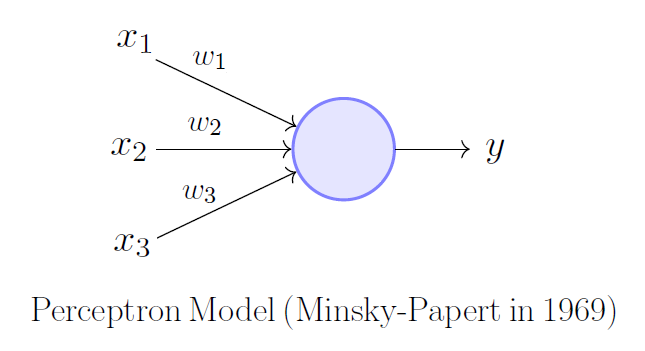

**ReLU (Rectified Linear Unit)**

    
$$\begin{array}{l}
\textrm{for}\;\textrm{vector}\;\mathit{\mathbf{x}}\;\textrm{and}\;\textrm{weight}\;\textrm{vector}\;\mathit{\mathbf{w}}\\
z={\mathit{\mathbf{w}}}^T \mathit{\mathbf{x}}=\sum_i^n x_i w_i \\
h\left(z\right)=\max \left(0,z\right)
\end{array}$$


**Sigmoid  function**

    
$$\begin{array}{l}
\textrm{for}\;\textrm{vector}\;x\;\textrm{and}\;\textrm{weight}\;\textrm{vector}\;\mathit{\mathbf{w}}\\
z={\mathit{\mathbf{w}}}^T \mathit{\mathbf{x}}=\sum_i^n x_i w_i \\
h\left(z\right)=\frac{1}{1+e^{-z} }
\end{array}$$


**Hyperbolic tangent  function**

    
$$\begin{array}{l}
\textrm{for}\;\textrm{vector}\;x\;\textrm{and}\;\textrm{weight}\;\textrm{vector}\;\mathit{\mathbf{w}}\\
z={\mathit{\mathbf{w}}}^T \mathit{\mathbf{x}}=\sum_i^n x_i w_i \\
h\left(z\right)=\tanh \left(z\right)
\end{array}$$


**Note1:** an additional weight $b$, known as **bias**, is generally used in order for the NN to identify noticeably complex patterns. So that $z=\sum_i^n x_i w_i +b={\left\lbrack \begin{array}{c}
\mathit{\mathbf{w}}\\
b
\end{array}\right\rbrack }^T \left\lbrack \begin{array}{c}
\mathit{\mathbf{x}}\\
1
\end{array}\right\rbrack$. Therefore, **from now on it will be assumed that the input **$\mathit{\mathbf{x}}$** will contain the "additional" one needed for the bias**.

Note2: the input and output data are usually normalized, to be in the range [-1,1], [0,1] or with mean 0 and standard deviation =1

Wiki page:

[https://en.wikipedia.org/wiki/Activation_function](https://en.wikipedia.org/wiki/Activation_function)

## **2. Feed Fordward Neural Network Architecture FFNN.**

In general, Feed-Fordward Neural Network can be composed of more than one hidden node, **which are linearly combined**, using weight vector ${\mathit{\mathbf{w}}}_{\textrm{out}}$, and each of these nodes has its own weight vector ${\mathit{\mathbf{w}}}_j \in R^n$, but **they usually use the same activation function** $h\left(\right)$.

The most basic FFNN architecture is composed of one layer of activation functions, commonly refered as **"hidden layer**", so that the estimated output at instant $i$of the network is: 


$${y^{\textrm{NN}} }_i =\sum_j^{n_h } w_{{\textrm{out}}_j } \;h\left({{\mathit{\mathbf{w}}}_j }^T {\mathit{\mathbf{x}}}_i \right)={\mathit{\mathbf{w}}}_{\textrm{out}}^T h\left(\left\lbrack \begin{array}{c}
{{\mathit{\mathbf{w}}}_1 }^T {\mathit{\mathbf{x}}}_i \\
\vdots \\
{{\mathit{\mathbf{w}}}_{n_h } }^T {\mathit{\mathbf{x}}}_i 
\end{array}\right\rbrack \right)={\mathit{\mathbf{w}}}_{\textrm{out}}^T h\left(\left\lbrack \begin{array}{c}
{{\mathit{\mathbf{w}}}_1 }^T \\
\vdots \\
{{\mathit{\mathbf{w}}}_{n_h } }^T 
\end{array}\right\rbrack {\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}} \right)={\mathit{\mathbf{w}}}_{\textrm{out}}^T h\left({\mathit{\mathbf{W}}}_{\textrm{in}} {\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}} \right)={\mathit{\mathbf{w}}}_{\textrm{out}}^T {\mathit{\mathbf{h}}}_i$$


where ${\mathit{\mathbf{W}}}_{\textrm{in}} \in R^{\textrm{nx}n_h }$ is a rectangular matrix and ${\mathit{\mathbf{h}}}_i \in R^n$ contains the values of the hidden layer at instant $i$.

## 3. Back Propagation

Back Propogation (BP) is the fundamental** iterative **algorithm for training feedforward Neural Networks (NN). BP is the result of using the Gradient Descent (GD) algorithm, ${\mathit{\mathbf{w}}}_{\textrm{new}} ={\mathit{\mathbf{w}}}_{\textrm{old}} -\alpha \frac{\partial C}{\partial {\mathit{\mathbf{w}}}_{\textrm{old}} \;}$, over the MSE cost function, $C=\sum_i^B {\left(y_i -{y_i }^{\textrm{NN}} \right)}^2$, and applying the chain rule $\frac{\partial C}{\partial w_j \;}=\sum_i^B \frac{\partial C}{\partial {y^{\textrm{NN}} }_i \;}\frac{\partial {y^{\textrm{NN}} }_i }{\partial h\;}\frac{\partial h}{\partial w_j }$ to each of the elememnts of the weight vectors in the NN, where $\frac{\partial C}{\partial {y^{\textrm{NN}} }_i \;}\frac{\partial {y^{\textrm{NN}} }_i }{\partial h\;}$ is the Propagated Error (PE) of the cost function with respect to the hidden layer.

The first step is to initialize input weights, ${\mathit{\mathbf{w}}}^{\left(0\right)} ,$ within a **small interval** centered around 0, commonly using a **random distribution **such as** uniform, normal, etc**. 

In **each iteration**, a **forward pass **is used to calculate the estimated output ${y_i }^{\textrm{NN}}$, for each instance $i$.  

Then a** backward pass,** directlly linked to the chain rule**,** is used to calculate the increments $\Delta \mathit{\mathbf{w}}=-\alpha \frac{\partial C}{\partial {\mathit{\mathbf{w}}}_{\textrm{old}} \;}$. Using the deltas, we can adjust the weights accordingly in each iteration.

Several iterations of BP are performed in order to adjust the weights $\mathit{\mathbf{w}}$in the network.

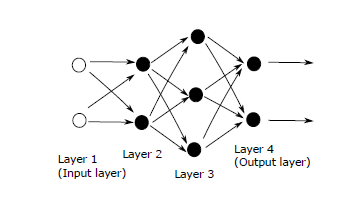

Paper:     https://arxiv.org/abs/1801.05894

ans = 0.0060

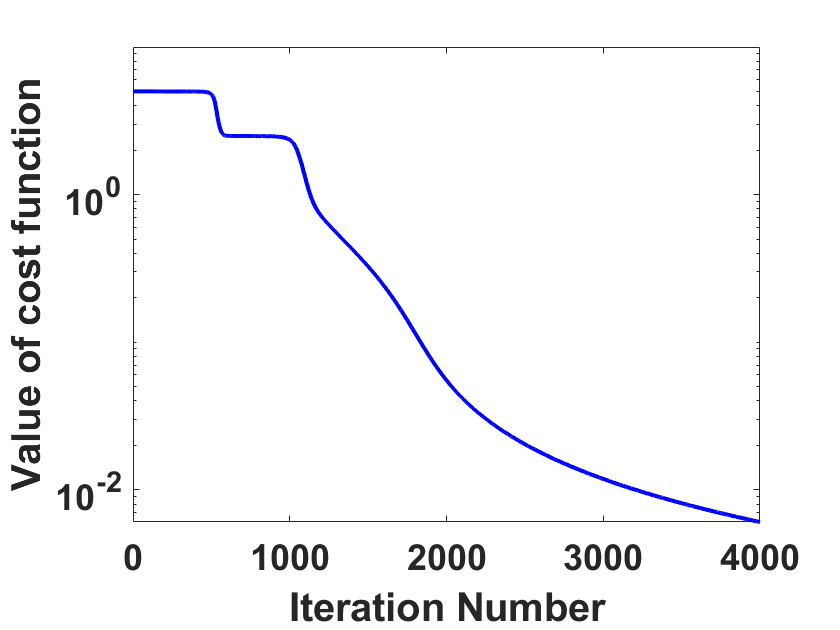

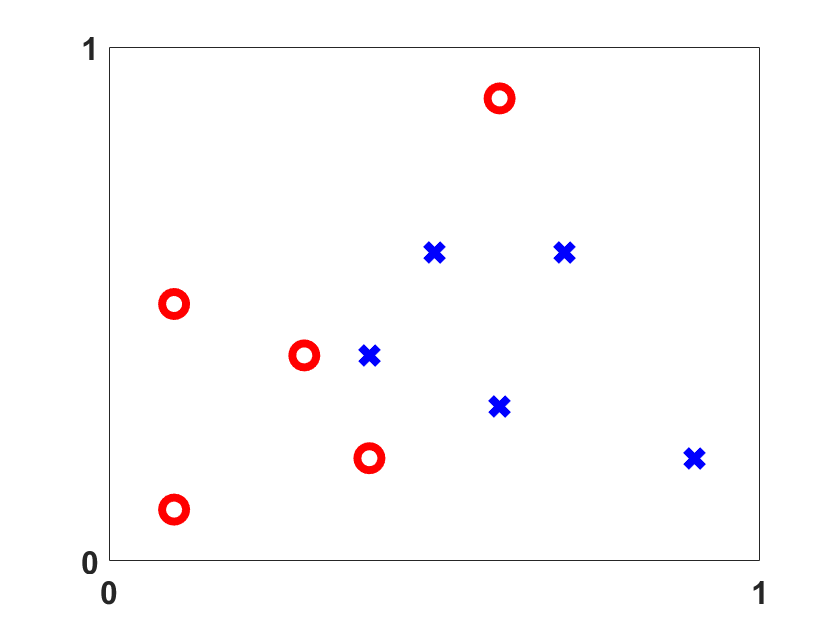

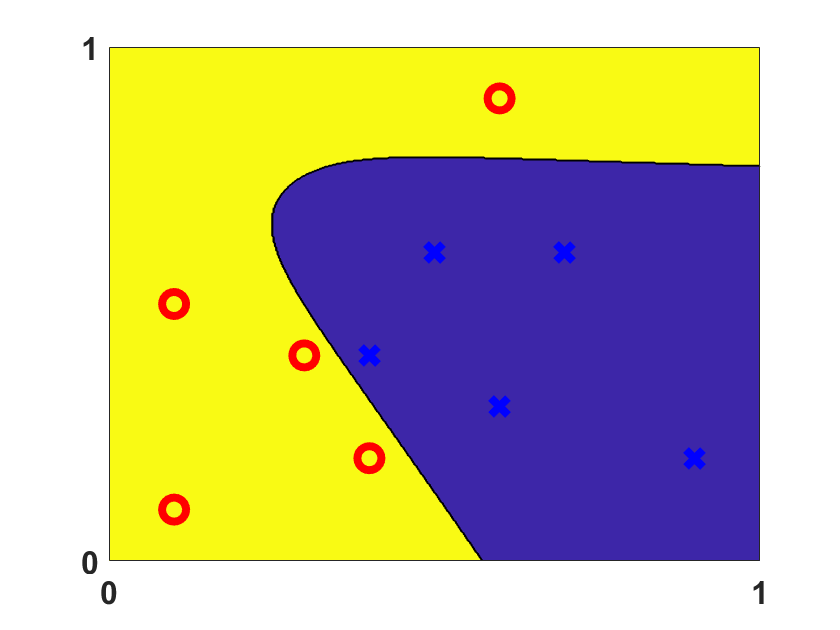

netbp_full

function y = activate(x,w,b,linear_flag)
%ACTIVATE  Evaluates the defined function.
%
%  x is the input vector/matrix,  y is the output vector/matrix
%  w contains the weights, b contains the shifts
%
%  The ith component of y is activate((Wx+b)_i)
if linear_flag==0
    %     y = 1./(1+exp(-(w*x+b))); % sigmoid function
    %     y = 0.5*tanh((w*x+b)/2)+0.5; % faster version of sigmoid function
    %     y = max(0, w*x); % ReLU function
    y = tanh(w*x+b); %Hyperbolic tangent function
else
    y=w*x+b;%Linear layer
end

end

function netbp_full
%NETBP_FULL
%   Extended version of netbp, with more graphics
%
%   Set up data for neural net test
%   Use backpropagation to train
%   Visualize results
%
% C F Higham and D J Higham, Aug 2017
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% DATA %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
x1 = [0.1,0.3,0.1,0.6,0.4,0.6,0.5,0.9,0.4,0.7];%First component of input
x2 = [0.1,0.4,0.5,0.9,0.2,0.3,0.6,0.2,0.4,0.6];%Second component of input
y = [ones(1,5) zeros(1,5); zeros(1,5) ones(1,5)];%Output/Target used to classifiy the input
%-----Normalization of the input------
min_x1=min(x1);
max_x1=max(x1);
x1n=2*(x1-min_x1)/(max_x1-min_x1)-1;
min_x2=min(x2);
max_x2=max(x2);
x2n=2*(x2-min_x2)/(max_x2-min_x2)-1;
%-------------------------------------
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% NN parameters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%---------------------------Two hidden-layer NN------------------------------
n_h=4;%number of hidden units (activation functions) in the first hidden layer.
n_h2=2;%number of hidden units (activation functions) in the second hidden layer.
%-----------------------------------------------------------------------------
% Weights and bias initialization using uniform distribution from [-a,a]
a=0.05;
W1 = a*(2*rand(n_h,2)-1);%First hidden layer weights
W2 = a*(2*rand(n_h2,n_h)-1);%Second hidden layer biases
W3 = a*(2*rand(2,n_h2)-1);%Linear layer weights
b1 = a*(2*rand(n_h,1)-1);%First hidden layer weights
b2 = a*(2*rand(n_h2,1)-1);%Second hidden layer biases
b3 = a*(2*rand(2,1)-1);%Linear layer biases
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure(1)
clf
s1 = subplot(1,1,1);
plot(x1(1:5),x2(1:5),'ro','MarkerSize',12,'LineWidth',4)
hold on
plot(x1(6:10),x2(6:10),'bx','MarkerSize',12,'LineWidth',4)
s1.XTick = [0 1];
s1.YTick = [0 1];
s1.FontWeight = 'Bold';
s1.FontSize = 16;
xlim([0,1])
ylim([0,1])

%%%%%%%%%%%%%%%%%%%%% NN training process%%%%%%%%%%%%%%%%%%%%%%%
% Forward and Back propagate
% Pick a training point at random
alpha = 0.05;%Learnin rate for BP.
N_iter = 4000;%Number of iterations.
savecost = zeros(N_iter,1);%cost function values across iterations
for counter = 1:N_iter
    %     x = [x1n(k); x2n(k)];%one single element of the input data set is used
    x = [x1n; x2n];%The whole input data set is used
    % Forward pass
    H1 = activate(x,W1,b1,0);%First hidden layer
    H2 = activate(H1,W2,b2,0);%Second hidden layer
    H3 = activate(H2,W3,b3,1);%linear layer
    % Backward pass
    %     delta4 = a4.*(1-a4).*(a4-y);
    %     delta3 = a3.*(1-a3).*(W4'*delta4);
    %     delta2 = a2.*(1-a2).*(W3'*delta3);
    PE3 = (H3-y);%PE of the linear layer
    PE2 = (1-H2.^2).*(W3'*PE3);%PE of the second hidden layer
    PE1 = (1-H1.^2).*(W2'*PE2);%PE of the first hidden layer
    % Gradient step
    W1 = W1 - alpha*PE1*x';%update for the weights in the first hidden layer
    W2 = W2 - alpha*PE2*H1';%update for the weights in the second hidden layer
    W3 = W3 - 0.1*alpha*PE3*H2';%update for the weights in the linear layer
    b1 = b1 - alpha*sum(PE1,2);%update for the weights in the first hidden layer
    b2 = b2 - alpha*sum(PE2,2);%update for the weights in the second hidden layer
    b3 = b3 - 0.1*alpha*sum(PE3,2);%update for the biases in the linear layer
    % Monitor progress
    newcost = cost(W1,W2,W3,b1,b2,b3,counter,N_iter);   % Cost function value
    savecost(counter) = newcost;
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure(2)
clf
semilogy([1:1:N_iter],savecost(1:1:N_iter),'b-','LineWidth',2)
savecost(N_iter)
xlabel('Iteration Number')
ylabel('Value of cost function')
set(gca,'FontWeight','Bold','FontSize',18)
print -dpng pic_cost.png

%%%%%%%%%%% Evaluate the NN in the 2D region [0,1]X[0,1]%%%%%%%%%%%%%%%%%%%
N = 500;
Dx = 1/N;
Dy = 1/N;
x1_vals = [0:Dx:1];
x2_vals = [0:Dy:1];
Aval=zeros(length(x1_vals),length(x1_vals));
Bval=zeros(length(x1_vals),length(x1_vals));
for k1 = 1:length(x1_vals)
    x1k = 2*(x1_vals(k1)-min_x1)/(max_x1-min_x1)-1;
    for k2 = 1:length(x1_vals)
        x2k = 2*(x2_vals(k2)-min_x2)/(max_x2-min_x2)-1;
        x_vals = [x1k;x2k];
        H1 = activate(x_vals,W1,b1,0);
        H2 = activate(H1,W2,b2,0);
        H3 = activate(H2,W3,b3,1);
        Aval(k2,k1) = H3(1);
        Bval(k2,k1) = H3(2);
    end
end
[X,Y] = meshgrid(x1_vals,x2_vals);

figure(3)
clf
s2 = subplot(1,1,1);
Mval = abs(Aval-1)<abs(Bval-1);
% Mval = Aval>Bval;
contourf(X,Y,Mval)
hold on
% colormap([1 1 1; 0.3 0.3 0.3])
plot(x1(1:5),x2(1:5),'ro','MarkerSize',12,'LineWidth',4)
plot(x1(6:10),x2(6:10),'bx','MarkerSize',12,'LineWidth',4)
s2.XTick = [0 1];
s2.YTick = [0 1];
s2.FontWeight = 'Bold';
s2.FontSize = 16;
xlim([0,1])
ylim([0,1])

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    %%%%%%%%%%%%%%%%%%%%%%%%%%%Cost function evaluation%%%%%%%%%%%%%%%%%%%%%
    function costval = cost(W2,W3,W4,b2,b3,b4,counter_co,N_iter_co)
        
        x_cost =[x1n;x2n];
        H1 = activate(x_cost,W2,b2,0);
        H2 = activate(H1,W3,b3,0);
        H3 = activate(H2,W4,b4,1);
        costval = norm(y-H3,2)^2;
    end
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
end